# H-reflex recruitment curve - Group data Analysis

Developed by Pedro Valadão (pvaladao@tuta.io). Last Modified: 10/05/2021.

*Sample: 15 CP + 15 TD + 1 SDR case study (5105). Pipeline: descriptive statistics - normality and equal variance tests - independent t-test. *

**Results**: The CP group Hmax/Mmax ratio [0.75 (SD: 0.28)] was not statistically different from TD [0.75 (SD: 0.26), t(31) = 0.03, p = 0.972, 95%CI = -0.190 to 0.197, power = 0.05, Hedge´s g = 0.01, 95%CI = -0.69 to 0.67] .Mmax was significantly higher in the TD group [4.8 (SD: 1.0)] as compared to the CP group [3.5 (SD: 1.8), p = 0.028, Hedge´s g = 0.91, 95%CI = 0.20 to 1.64]. 

SDR subject had the lowest Hmax/Mmax value (0.11), which is expected since most Ia connections were severed. 

## Hmax/Mmax

*CP does not have normal distribution, groups have equal variances - Wilcoxon rank sum test was used. *

### Preparing data/ Group summary

load('Recruitment_all.mat')
H_all.Group = categorical(H_all.Group); %make group a categorical var
HM_results = H_all(H_all.Subject ~= "5105",:); %exclude case study (5105)
SDR_H = H_all(H_all.Subject == "5105",:); % var for case study.
HM_descriptives = groupsummary(HM_results,"Group",{'mean','std','median','min','max','var'},'Hmax_Mmax')

HM_descriptives = 2×8 table
    Group    GroupCount     mean_Hmax_Mmax        std_Hmax_Mmax      median_Hmax_Mmax       min_Hmax_Mmax       max_Hmax_Mmax        var_Hmax_Mmax   
    _____    __________    _________________    _________________    _________________    _________________    ________________    __________________

     CP          14        0.794433553490702     0.27412450764144    0.889746960666201    0.226044273622791    1.11348174901838    0.0751442456896617
     TD          15        0.780189845933213    0.236807615586948    0.796502863893219    0.310789048129985    1.07116340031456    0.0560778467999757


### Kurtosis, Skewness, Normality and Equal variances.

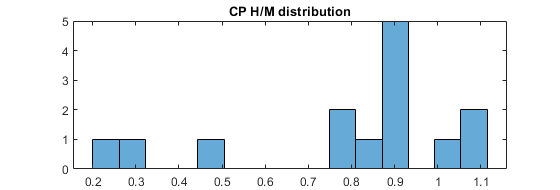

CP_HM = HM_results.Hmax_Mmax(HM_results.Group == "CP"); %Hmax/Mmax CP group
TD_HM = HM_results.Hmax_Mmax(HM_results.Group == "TD"); % Hmax/Mmax TD group
histogram(CP_HM,15),title('CP H/M distribution'),

histogram(TD_HM,15), title('TD H/M distribution'),
kurtosis_CP = kurtosis(CP_HM)

kurtosis_CP =            2.8359781774704


kurtosis_TD = kurtosis(TD_HM)

kurtosis_TD =            2.3729619798815


skewness_CP = skewness(CP_HM)

skewness_CP =          -1.01259821838854


skewness_TD = skewness(TD_HM)

skewness_TD =         -0.559292408799602


normalitytest(CP_HM'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.9862 	     0.2850                 1 
KS Stephens Modification       1.0435 	     0.0100                 0 
KS Marsaglia Method            0.9862 	     0.2391                 1 
KS Lilliefors Modification     0.2636 	     0.0093                 0 
Anderson-Darling Test          0.9852 	     0.0131                 0 
Cramer- Von Mises Test         0.1769 	     0.0106                 0 
Shapiro-Wilk Test              0.8512 	     0.0230                 0 
Shapiro-Francia Test           0.8557 	     0.0273                 0 
Jarque-Bera Test               2.4082 	     0.3000                 1 
DAgostino & Pearson Test       3.8497 	     0.1459                 1 


normalitytest(TD_HM');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.4759 	     0.9773                 1 
KS Stephens Modification       0.5016 	     0.1500                 1 
KS Marsaglia Method            0.4759 	     0.9564                 1 
KS Lilliefors Modification     0.1229 	     0.2000                 1 
Anderson-Darling Test          0.4043 	     0.3542                 1 
Cramer- Von Mises Test         0.0543 	     0.4495                 1 
Shapiro-Wilk Test              0.9275 	     0.2503                 1 
Shapiro-Francia Test           0.9396 	     0.3193                 1 
Jarque-Bera Test               1.0278 	     0.5982                 1 
DAgostino & Pearson Test       1.2587 	     0.5329                 1 


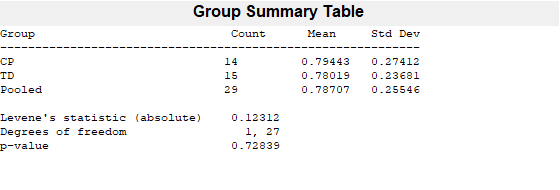

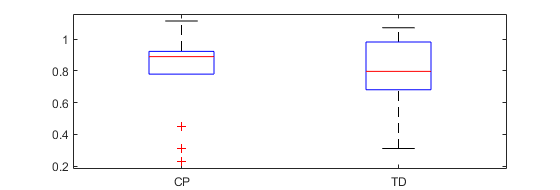

p =          0.728394209613645


p = vartestn(HM_results.Hmax_Mmax,HM_results.Group,'TestType','LeveneAbsolute')

p = vartestn(HM_results.Hmax_Mmax,HM_results.Group,'TestType','LeveneQuadratic','display','off')

p =          0.571907283409151


### Independent t-test, Power calculation, Effect Size (Hedge's g).

[p,h,stats] = ranksum(CP_HM,TD_HM, 'method','exact') %Wilcoxon rank sum test, exact p calculation

p =          0.590744926814199


h = logical
   0


stats = struct with fields:
    ranksum: 223


median(CP_HM)

ans =          0.889746960666201


iqr(CP_HM)

ans =           0.14329275804148


median(TD_HM)

ans =          0.796502863893219


iqr(TD_HM)

ans =          0.300255241773533


### Case study values.

SDR_H = H_all(H_all.Subject == "5105",:) %SDR data

SDR_H = 1×6 table
    Subject    Group     Test            Hmax                 Mmax              Hmax_Mmax    
    _______    _____    _______    _________________    ________________    _________________

    "5105"      CP      "Pre_1"    0.583425808708791    5.50599664588139    0.105961889596356


## Mmax

The CP group does not have normally distributed data, and groups do not have equal variances -  the ranksum test was utilized. TD had statistically higher Mmax compared to CP. This result is not reported in the manuscript, Mmax is only used in it to normalize Hmax. 

### Group summary

Mmax_descriptives = groupsummary(HM_results,"Group",{'mean','std','median','min','max','var'},'Mmax')

Mmax_descriptives = 2×8 table
    Group    GroupCount       mean_Mmax            std_Mmax          median_Mmax           min_Mmax            max_Mmax            var_Mmax    
    _____    __________    ________________    ________________    ________________    ________________    ________________    ________________

     CP          14        3.61298693065218    1.88727803726989    2.51742118713365    1.45564588746971    6.65194211132454    3.56181838996128
     TD          15        4.78740910303042    1.04994771336563     4.9688249322462    2.55674878785226    6.60489317525268    1.10239020080171


CP_Mmax = HM_results.Mmax(HM_results.Group == "CP"); %Mmax CP group
TD_Mmax = HM_results.Mmax(HM_results.Group == "TD"); %Mmax TD group

### Kurtosis, Skewness, Normality and Equal variances.

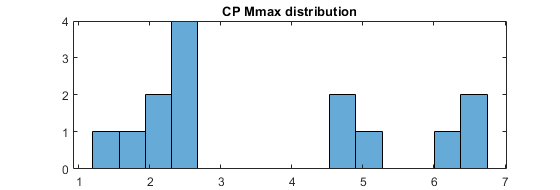

histogram(CP_Mmax,15),title('CP Mmax distribution'),

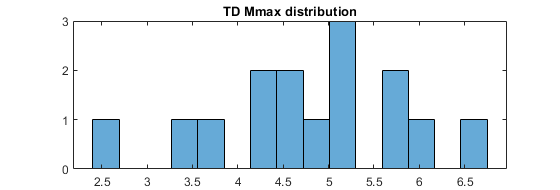

histogram(TD_Mmax,15), title('TD Mmax distribution'),

kurtosis_Mmax_CP = kurtosis(CP_Mmax)

kurtosis_Mmax_CP =           1.62051653498692


kurtosis_Mmax_TD = kurtosis(TD_Mmax)

kurtosis_Mmax_TD =           2.78052288711404


skewness_Mmax_CP = skewness(CP_Mmax)

skewness_Mmax_CP =          0.460192985075285


skewness_Mmax_TD = skewness(TD_Mmax)

skewness_Mmax_TD =         -0.361068686749579


normalitytest(CP_Mmax'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.0035 	     0.2663                 1 
KS Stephens Modification       1.0618 	     0.0100                 0 
KS Marsaglia Method            1.0035 	     0.2223                 1 
KS Lilliefors Modification     0.2682 	     0.0073                 0 
Anderson-Darling Test          0.9193 	     0.0175                 0 
Cramer- Von Mises Test         0.1621 	     0.0165                 0 
Shapiro-Wilk Test              0.8583 	     0.0289                 0 
Shapiro-Francia Test           0.8794 	     0.0542                 1 
Jarque-Bera Test               1.6042 	     0.4484                 1 
DAgostino & Pearson Test       3.9060 	     0.1418                 1 


normalitytest(TD_Mmax');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.3947 	     0.9977                 1 
KS Stephens Modification       0.4161 	     0.1500                 1 
KS Marsaglia Method            0.3947 	     0.9931                 1 
KS Lilliefors Modification     0.1019 	     0.2000                 1 
Anderson-Darling Test          0.1666 	     0.9390                 1 
Cramer- Von Mises Test         0.0247 	     0.9132                 1 
Shapiro-Wilk Test              0.9842 	     0.9903                 1 
Shapiro-Francia Test           0.9800 	     0.9309                 1 
Jarque-Bera Test               0.3560 	     0.8369                 1 
DAgostino & Pearson Test       0.7148 	     0.6995                 1 


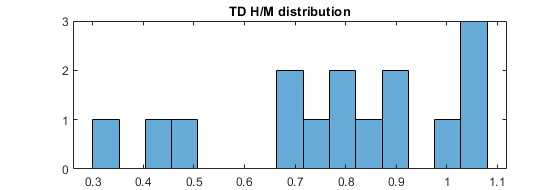

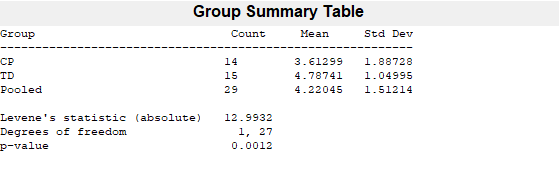

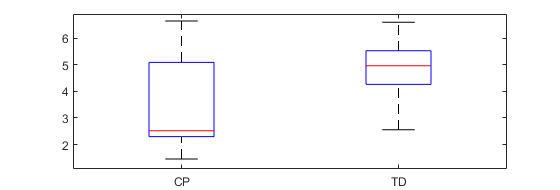

p =        0.00124698858710955


p = vartestn(HM_results.Mmax,HM_results.Group,'TestType','LeveneAbsolute')

p = vartestn(HM_results.Mmax,HM_results.Group,'TestType','LeveneQuadratic','display','off')

p =        0.00789811632881162


### Independent t-test, Power calculation, Effect Size (Hedge's g).

[p,h,stats] = ranksum(CP_Mmax,TD_Mmax, 'method','exact') %Wilcoxon rank sum test, exact p calculation

p =           0.10230859802297


h = logical
   0


stats = struct with fields:
    ranksum: 172


median(CP_Mmax)

ans =           2.51742118713365


iqr(CP_Mmax)

ans =           2.79951831314108


median(TD_Mmax)

ans =            4.9688249322462


iqr(TD_Mmax)

ans =           1.26948601577969
